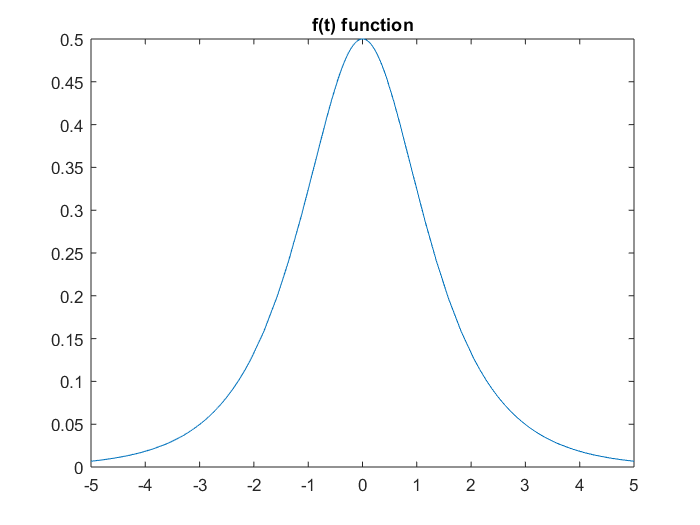

format long
syms f(t)

% the given function  and the decorator
f(t) = 1./(exp(t)+exp(-t));
p = @(t) 1./(exp(t)+exp(-t));

% the threshold for error
thresh = 0.0001;

% plot the function to see where and if it saturates 
fplot(f(t))
title('f(t) function')

% find the actual answer for the function going to infinity
actual = integral(p,0,Inf)

actual =    0.785398163397448


integral(p,0,6)

ans =    0.782919416297423


integral(p,0,20)

ans =    0.785398163397454


% since the function saturates at [6,inf) we can find finite boundaries
a = 0;
b = 20;

% the number of segments/points that will be used , assume >1
N_s = 1; % actual 47
% set S = 0
S = 0;

% check if the absolute errorv is larger than the threshold
while(abs(S-actual) > thresh)
    % reset the sum of of area segments under the curve
    S = 0;
    % find the step size
    dx = (b-a)/N_s;

    for i=1:N_s
        % calculate the integral using the simpsons method 
        x = a + (i-1)*dx;
        y = (dx/6)*(f(x) + 4*f(x+dx/2) + f(x + dx));
        S = S + y;
    end
    % increment the number of segments
    N_s = N_s + 1;
end
N_s = N_s - 1

N_s =     19


absoluteError = double(abs(S-actual))

absoluteError =      8.870116469052163e-05


double(S)

ans =    0.785309462232758
